Ajuste lineal vds_id

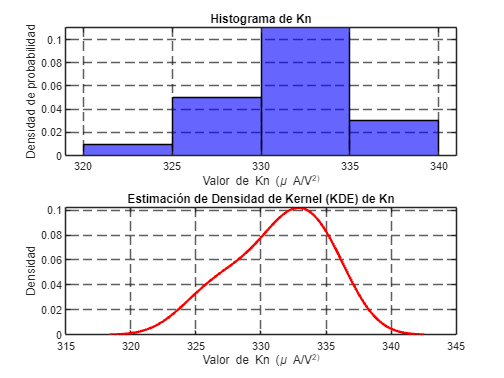

% Últimos datos de Kn modificados
Kn1 = [327.12, 333.06, 331.47, 328.12, 325.30];  % Valores de Kn del NMOS_1
Kn2 = [324.92, 330.87, 332.33, 331.63, 331.20];  % Valores de Kn del NMOS_2
Kn3 = [329.24, 333.84, 335.24, 334.34, 332.05];  % Valores de Kn del NMOS_3
Kn4 = [327.74, 335.25, 335.98, 334.88, 333.66];  % Valores de Kn del NMOS_4

% Concatenar todos los valores de Kn en un solo vector
Kn_total = [Kn1, Kn2, Kn3, Kn4];

% Crear figura para el histograma y KDE
figure;

% --- Histograma ---
subplot(2, 1, 1);  % Crear un subgráfico para el histograma
histogram(Kn_total, 'Normalization', 'pdf', 'BinMethod', 'auto', 'FaceColor', 'b', 'EdgeColor', 'k');
set(gca, 'GridLineStyle', '--', 'GridColor', [0.1, 0.1, 0.1], 'GridAlpha', 0.7);
title('Histograma de Kn');
xlabel('Valor de Kn (\mu A/V^2)');
ylabel('Densidad de probabilidad');
grid on;

% --- Kernel Density Estimation (KDE) ---
subplot(2, 1, 2);  % Crear un subgráfico para el KDE
[f, xi] = ksdensity(Kn_total);  % Estimación de densidad de kernel
plot(xi, f, 'r', 'LineWidth', 2);  % Graficar KDE
set(gca, 'GridLineStyle', '--', 'GridColor', [0.1, 0.1, 0.1], 'GridAlpha', 0.7);
title('Estimación de Densidad de Kernel (KDE) de Kn');
xlabel('Valor de Kn (\mu A/V^2)');
ylabel('Densidad');
grid on;

% Ajuste lineal de la forma y = p(1)*x + p(2)
% Ajuste lineal de la forma y = m*x + b
% Vectores de datos de Kn y R
Kn1 = [327.12, 333.06, 333.53, 332.41, 331.41];  % Valores de Kn del NMOS_1
Kn2 = [324.92, 330.87, 332.33, 331.63, 331.20];  % Valores de Kn del NMOS_2
Kn3 = [329.24, 333.84, 335.24, 334.34, 332.05];  % Valores de Kn del NMOS_3
Kn4 = [327.74, 335.25, 335.98, 334.88, 333.66];  % Valores de Kn del NMOS_4

R1 = [2014, 3991, 6168, 8160, 9990];  % Valores de R del NMOS_1
R2 = [1990, 4175, 6143, 8000, 10010];  % Valores de R del NMOS_2
R3 = [2024, 3967, 5990, 7940, 10010];  % Valores de R del NMOS_3
R4 = [1990, 4175, 6143, 8000, 10010];  % Valores de R del NMOS_4

% Concatenación de los vectores de Kn y R en el mismo orden
Kn_total = [Kn1, Kn3, Kn4,Kn2];  % Todos los valores de Kn concatenados
R_total = [R1, R3, R4,R2];  % Todos los valores de R concatenados

% Mostrar los vectores concatenados
disp('Vector total de Kn:');

Vector total de Kn:


disp(Kn_total);

  327.1200  333.0600  333.5300  332.4100  331.4100  329.2400  333.8400  335.2400  334.3400  332.0500  327.7400  335.2500  335.9800  334.8800  333.6600  324.9200  330.8700  332.3300  331.6300  331.2000



disp('Vector total de resistencias R:');

Vector total de resistencias R:


disp(R_total);

        2014        3991        6168        8160        9990        2024        3967        5990        7940       10010        1990        4175        6143        8000       10010        1990        4175        6143        8000       10010




% Ajuste lineal de la forma y = m*x + b para R vs Kn
p_kn = polyfit(R_total, Kn_total, 1);  % p_kn(1) es la pendiente y p_kn(2) es la intersección

% Evaluación de la recta ajustada para R vs Kn
Kn_ajustado = polyval(p_kn, R_total);

% Gráfica de los datos y del ajuste
figure;
plot(R_total, Kn_total, 'bo', 'MarkerFaceColor', 'b');  % Datos experimentales
set(gca, 'GridLineStyle', '--', 'GridColor', [0.1, 0.1, 0.1], 'GridAlpha', 0.7);
hold on;
%plot(R_total, Kn_ajustado, '-r', 'LineWidth', 2);  % Línea ajustada
xlabel('Resistencia R (\Omega)');
ylabel('Kn (\mu A/V^2)');
title('Ajuste de $K_n$ vs $R$', 'Interpreter', 'latex');
legend('Datos experimentales', 'Ajuste lineal', 'Location', 'southeast');

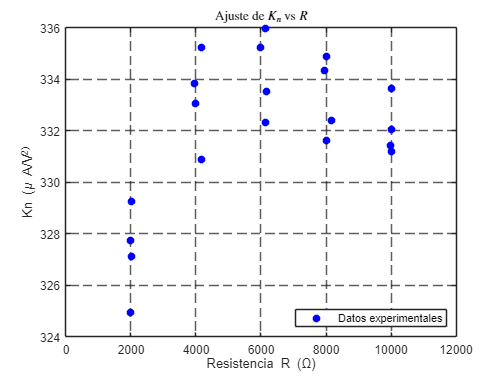

grid on;


% Mostrar parámetros del ajuste
b_kn = p_kn(2);  % Intersección con el eje Y
m_kn = p_kn(1);  % Pendiente de la recta

disp(['Intersección con el eje Y (b): ', num2str(b_kn)]);

Intersección con el eje Y (b): 329.0486


disp(['Pendiente de la recta (m): ', num2str(m_kn)]);

Pendiente de la recta (m): 0.00049408
